# Analyze PLL Using MATLAB

The goal of this exercise is to compute the frequency response and step resonse of a charge-pump PLL **using linear system assumptions**. To do, so we'll first use the aid of Control System Toolbox functions and then without them. This exercise assumes the PLL parameters have already been chosen.

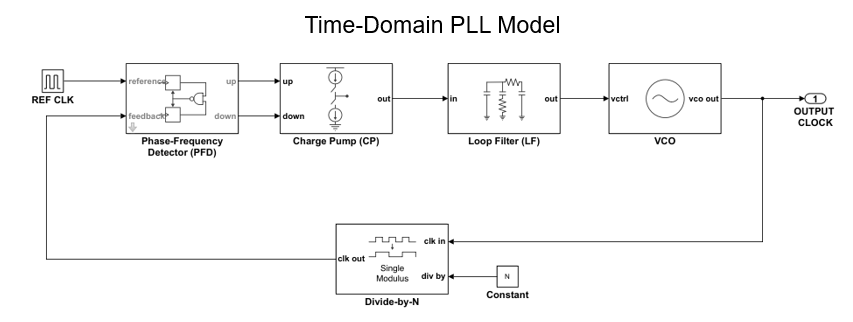

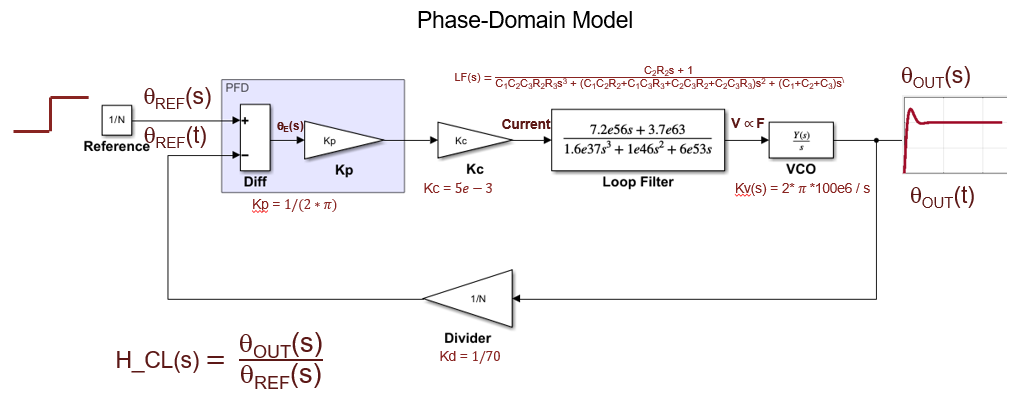

PLOT_IR = 1; % plot intermediate results


## 1. Compute and plot frequency response (FR) from transfer function (TF) using Control System Toolbox (CST) functions

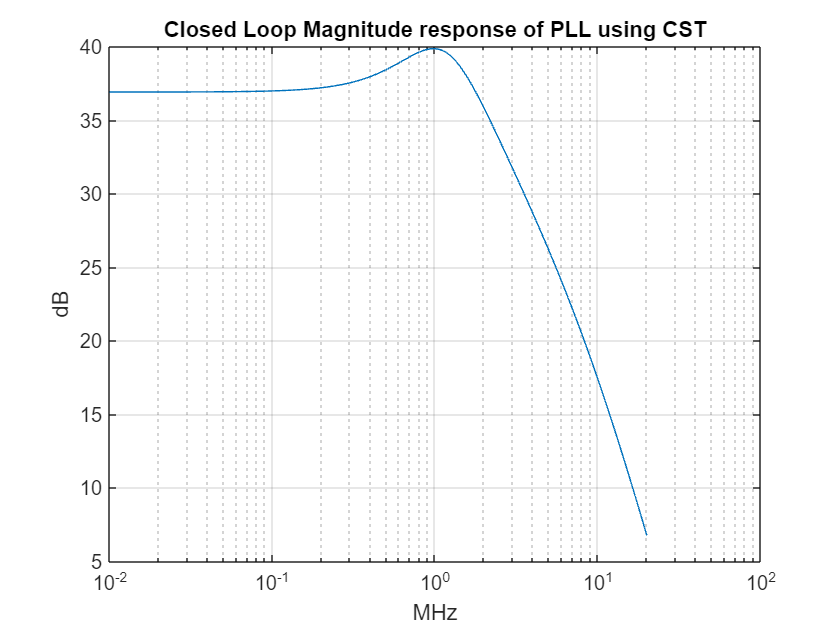

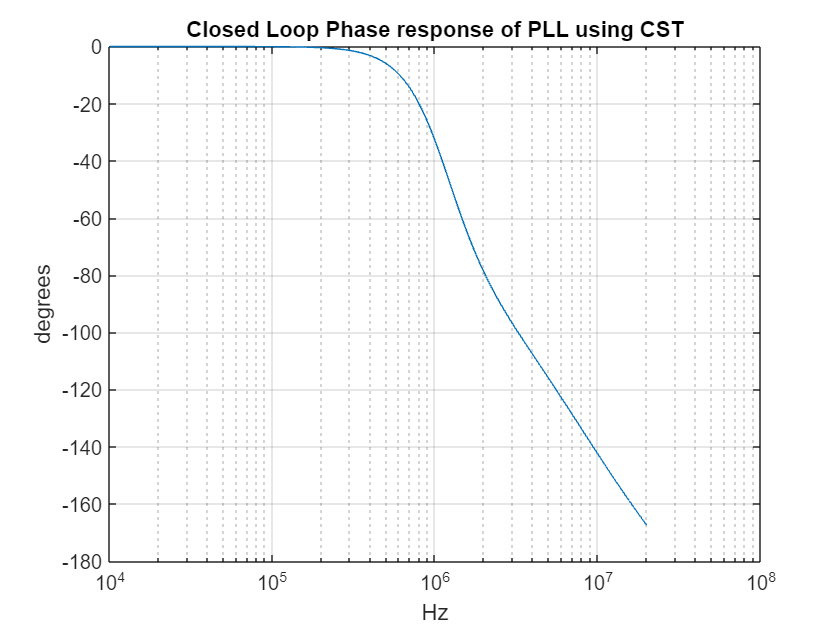

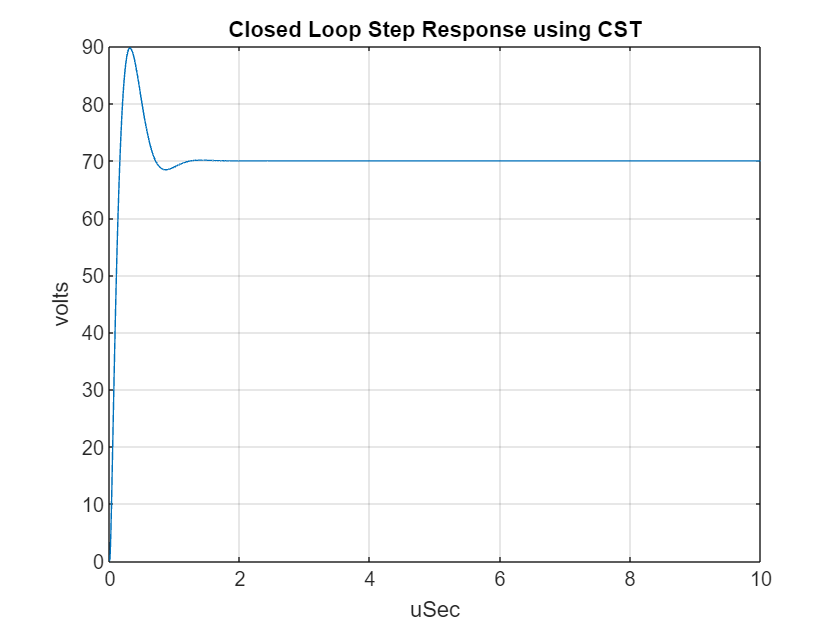

% Compute Closed-loop phase-domain response of PLL (REF to OUT) using CST functions
s = tf('s');
Kc = 5e-3;   % CP current in amps
num = [716e54 3.74e63];
den = [15.8e36 10.4e45 588e51 0];
LF = tf(num,den);  
Kvco = 100e6; % Hz/Volt
N = 70;       % divider value
H_cst = feedback(Kc*(Kvco/s)*LF,1/N);
BW = 20e6;
w = 2*pi*[0:10e3:20e6];
[mag,phz,wout] = bode(H_cst,w);
f_cst = wout/(2*pi);
mag_dB_cst = 20*log10(abs(squeeze(mag)));
% compute step response 
t_cst = [0:1e-9:10e-6];
sr_cst = step(H_cst,t_cst);
if PLOT_IR
    figure(1);semilogx(f_cst/1e6,mag_dB_cst);
    xlabel('MHz');ylabel('dB');grid on;
    title('Closed Loop Magnitude response of PLL using CST');
    phz_deg = unwrap(squeeze(phz));
    figure(2);semilogx(f_cst,phz_deg);
    xlabel('Hz');ylabel('degrees');grid on;
    title('Closed Loop Phase response of PLL using CST');  
    figure(3);plot(t_cst*1e6,sr_cst);grid on
    title('Closed Loop Step Response using CST')
    xlabel('uSec');ylabel('volts')
end

## Extract SR from FR

% wout = 2*pi*[0:BW/200:BW];
% [FR,wout] = freqresp(H_cst,wout);
% FR = squeeze(FR);
% %figure;plot(wout/6.28,20*log10(abs(FR)));grid on
% FR2 = [FR;conj(FR(end-1:-1:2))];
% ir_der = ifft(FR2,'symmetric');
% L = length(ir_der);
% Ts = .5/(BW);
% t_cst_der = [0:Ts:(L-1)*Ts];
% sr_cst_der = cumsum(ir_der);
% if PLOT_IR
%     figure;
%     plot(t_cst*1e6,sr_cst,'r',t_cst_der*1e6,sr_cst_der,'b-o'); hold on;
%     grid on;
%     xlabel('uSec')
%     title('Derived from CST FR');
%     legend('CST','CSR derived')
% end

## 2. Derive FR and SR w/out using CST functions

Derivation is based on (1) polynomial multiplication in Laplace domain and (2) inverse FFT

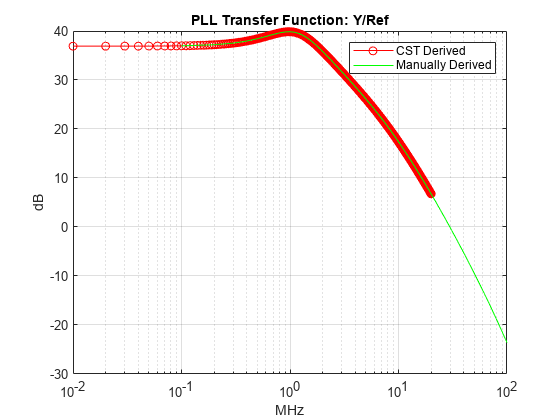

tsim    = 10e-6;     % time range of interest for step response
BW      = 20e6;      % frequency range of interest
Fs      = 10*BW;     % sample at least 2x higher than BW
Ts      = 1/Fs;      % sample period
npts    = round(tsim*Fs);  
% ensure npts is an even number, simplifies domain conversion
if mod(npts,2) == 1
    npts = npts + 1;
end
dF = Fs/npts;        % spacing in frequency
% not starting fvec at 0 since we'll be dividing by zero during
% the semi-analytical derivation. We will handle DC separately
% since DC is straight-forward for a PLL.
% Instead start fvec at 1 dF offset.
fvec = [dF:dF:dF*(npts-1)];
fvec = fvec(1:npts/2); % from 1*dF to Nyquist, not from DC
sL = j*2*pi*fvec; % laplacian s vector in numerical form, not symbolic
% coeffs function returns coefficients from lowest to highest order
n = [716e54 3.74e63];
d = [15.8e36 10.4e45 588e51 0];
%n2 = fliplr(double(coeffs(n)));
%d2 = fliplr(double(coeffs(d)));
%d2 = [d2 0];
%Z_LF = polyval(n,sL)./polyval(d,sL);
% equivalent of polyval using basic arithmetic
clear Z_LF
for k = 1:length(sL)
   Z_LF(k) = (n(1)*sL(k) + n(2)) ./ (d(1)*sL(k)^3 + d(2)*sL(k)^2 + d(3)*sL(k));
end
% Open loop TF
G = Kc*Kvco*Z_LF./sL;
% Closed loop transfer function: Out/Ref
H_CL_man(2:npts/2+1) = G./(1+G/N);
% Add in the DC point after-the-fact and updated fvec accordingly
H_CL_man(1) = N; 
f_man = [0 fvec];
mag_dB_man = 20*log10(abs(H_CL_man(1:npts/2+1)));

if PLOT_IR
    figure;semilogx(f_cst/1e6,mag_dB_cst,'r-o',f_man/1e6,mag_dB_man,'g');
    title('PLL Transfer Function: Y/Ref');
    xlabel('MHz');
    ylabel('dB');grid on;
    legend('CST Derived','Manually Derived')
end

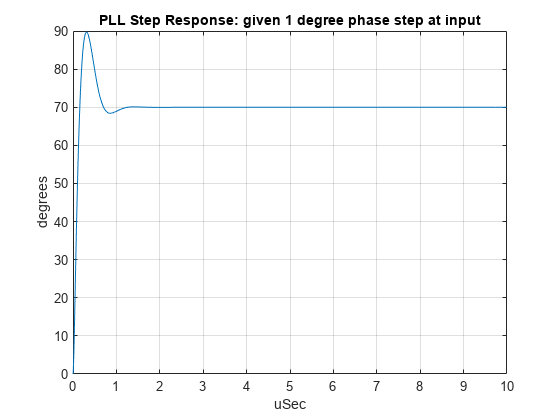


%% compute SR at output
H_CL_1 = [H_CL_man conj(H_CL_man(end-1:-1:2)) ];   % ds = double-sided
H_CL_1(npts/2+1) = 0;
ir_man = ifft(H_CL_1, 'symmetric');
t_man = (0:npts-1)'*Ts;
sr_man = zeros(npts,1); % sr = step response
for k = 2:npts
    sr_man(k) = sr_man(k-1) + ir_man(k);
end

if PLOT_IR
    figure;
    plot(t_man*1e6,sr_man);grid on;
    xlabel('uSec');
    ylabel('degrees')
    title('PLL Step Response: given 1 degree phase step at input')
end

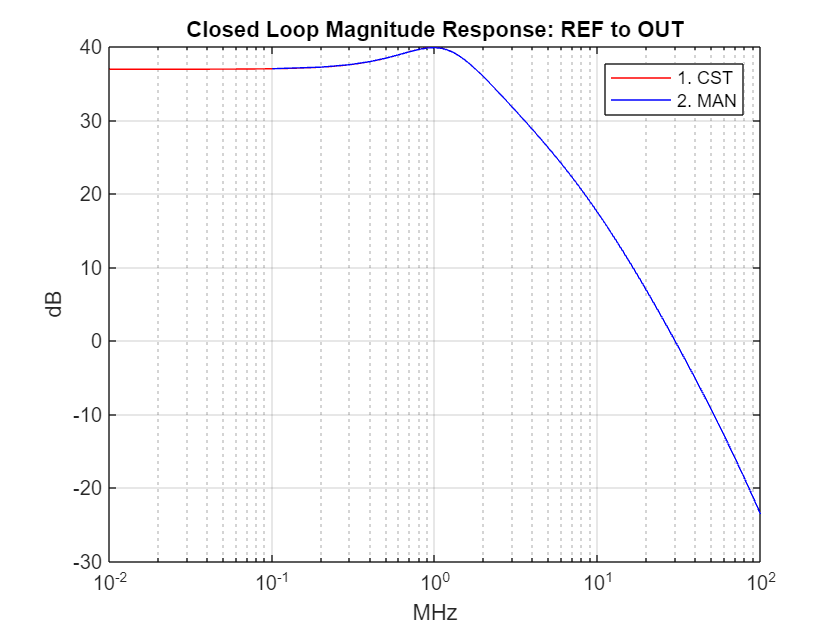

% Final Comparison Plots
figure;
semilogx(f_cst/1e6,mag_dB_cst,'r',f_man/1e6,mag_dB_man,'b');
grid on;
xlabel('MHz')
ylabel('dB');
title('Closed Loop Magnitude Response: REF to OUT')
legend('1. CST','2. MAN')

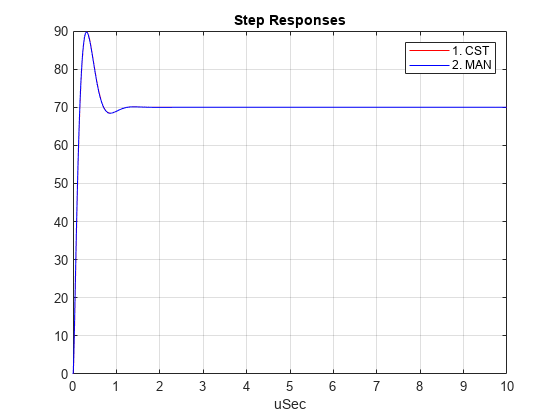


figure;
plot(t_cst*1e6,sr_cst,'r',t_man*1e6,sr_man,'b');
grid on;
xlabel('uSec')
title('Step Responses')
legend('1. CST','2. MAN')

## 3. Optional: Derive Loop Filter Transfer Function Symbolically

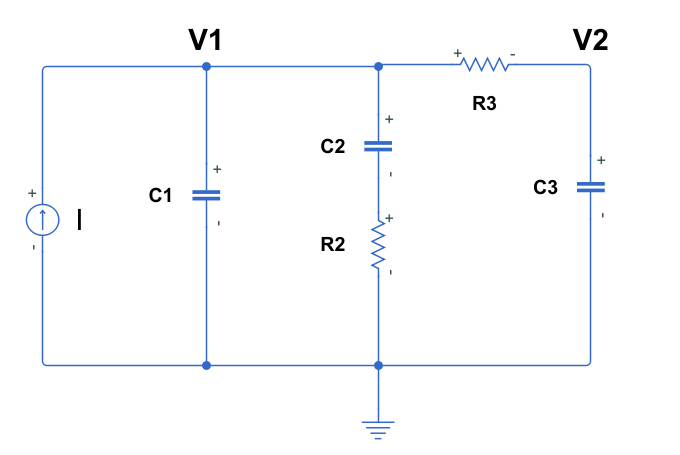

Third order Loop Filter TF Derivation

syms V1 V2 s I TF C1 C2 C3 R2 R3;
eqn1 = I == V1*C1*s + V1/(R2 + 1/(C2*s)) + (V1 - V2)/R3;
eqn2 = (V1-V2)/R3 == V2*C3*s;
eqn3 = TF == V2/I;
result = solve([eqn1,eqn2,eqn3],TF,I,V2);
TF_LF = collect(result.TF,s)

$$TF\_LF = \frac{\left(C_{2}\,R_{2}\right)\,s+1}{\left(C_{1}\,C_{2}\,C_{3}\,R_{2}\,R_{3}\right)\,s^{3}+\left(C_{1}\,C_{2}\,R_{2}+C_{1}\,C_{3}\,R_{3}+C_{2}\,C_{3}\,R_{2}+C_{2}\,C_{3}\,R_{3}\right)\,s^{2}+\left(C_{1}+C_{2}+C_{3}\right)\,s}$$

### Assign values to the loop filter R's and C's

R2   = 1.33e3;   % Loop Filter (LF) resistance for second order response (ohms)
R3   = 17e3;    % LF resistance for third order response (ohms)
C1   = 13e-12; % LF direct capacitance (F)
C2   = 144e-12; % LF capacitance for second order response (F)
C3   = 0.1e-12; % LF for third order response (F)

### **Compute TF of LF using component values**

syms V1 V2 s I TF
C1 = sym(C1);
C2 = sym(C2);
C3 = sym(C3);
R2 = sym(R2);
R3 = sym(R3);
eqn1 = I == V1*C1*s + V1/(R2 + 1/(C2*s)) + (V1 - V2)/R3;
eqn2 = (V1-V2)/R3 == V2*C3*s;
eqn3 = TF == V2/I;
result = solve([eqn1,eqn2,eqn3],TF,I,V2);
disp('3rd Order Loop Filter Transfer Function');
TF_LF = collect(result.TF,s);
TF_LF_for_humans = vpa(TF_LF,3) % human viewable form
[n,d] = numden(TF_LF);
num = sym2poly(n);
den = sym2poly(d);

Take the above derived **num** and **den** variables and substitute into section 1 of this script.